## **CU Anschutz-Medtronic Percieve Collaboration**

The purpose of this report is to illustarte key findings from the data acquisition and early analysis portion of this study. 

This section loads in variables that are useful to the other fuctions. Further, this section helps to process files coming from a patient with either single or double batteries, enhancing the modularity of the code. 

%%
clear
cd('C:\Users\sydne\Documents\github\perceive')
%jsonFiles = 'Report_Json_Session_Report_20210604T094200.json';
jsonFiles = 'pt2_0604_rl_survey.json'; 
cd('C:\Users\sydne\Documents\github\perceive')
js = jsondecode(fileread(jsonFiles));

channels = unique({js.LfpMontageTimeDomain.Channel}, 'stable');
leng = numel({js.LfpMontageTimeDomain.Channel});
sides = {'LEFT', 'RIGHT'};
startindex = 1; 
if any((contains(channels, sides{1}))) && any((contains(channels, sides{2}))) 
        doubleBattery = false; 
        %json has both left and right data 
        channelsLeft = channels(contains(channels, sides{1}));
        channelsRight = channels(contains(channels, sides{2}));
        highestBetas = cell(2);
    else 
        doubleBattery = true; 
end 

#### Frequency vs power plot for all contact pairs

After data is collected from Brainsense, the three trials are averaged and presented as a single line. All six pairs are represented. Smoothing has maintained the shape of the curve but altered the power, thus not always matching the maximum power reported. 

s1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.5838 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


The highest beta comes from contact pair 02


s1 =   Axes with properties:

             XLim: [0 1]
             YLim: [0 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.3412]
            Units: 'normalized'

  Show all properties


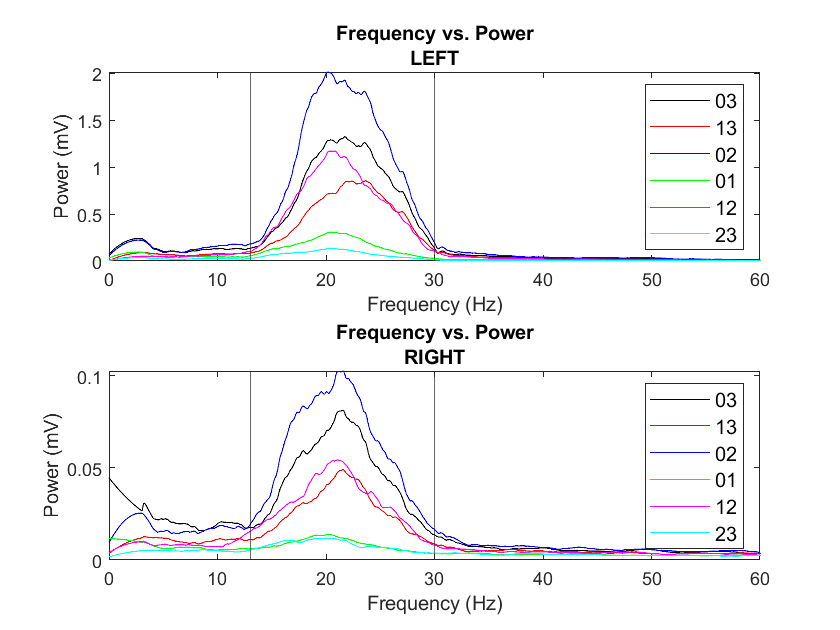

The highest beta comes from contact pair 02


% t = tiledlayout(2, 1, 'Padding', "tight")    
for  i = 1:2
    s1 = subplot(2, 1, i)
   % ax = gca;
   s1.FontSize = 14; 
    
        %nexttile
        channels2 = channels(contains(channels,sides{i}));
        colors = 'krbgmc';
        maxValues = zeros(length(channels2), 1);
        for c=1:length(channels2)
            maxValues(c) = tempAvgPlot(startindex, leng, js, channels2{c}, colors(c));
            hold on;
        end
        
        if i == 1 
            maxValuesLeft = maxValues; 
        else 
            maxValuesRight = maxValues; 
        end
        
        [M, I] = max(maxValues);
        highestBeta = channels2{I};
        highestBetas{i} = highestBeta;
        
        %add all the plot info
        xline(13);
        xline(30);
        
        %formats the channels to be suitable for the legend 
        legendChan = cell(6);
        oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'}; 
        newchar = {''}; 
        oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'}; 
        newnum = {'0', '1', '2', '3'};
        for b = 1:length(channels2)
            legendChan{b} = replace(channels2{b}, oldchar, newchar);
            legendChan{b} = replace(legendChan{b}, oldnum, newnum);
        end
        legend(legendChan{1}, legendChan{2}, legendChan{3}, legendChan{4}, legendChan{5}, legendChan{6}, 'FontSize', 10)
        
        
        title(["Frequency vs. Power", sides{i}])
        xlim([0 60])
        xlabel("Frequency (Hz)")
        ylabel("Power (mV)")
        
        disp(['The highest beta comes from contact pair ', legendChan{I}])       
end


%saveas(ax, 'assfnclinic.fig')

#### Compare beta between contacts with standard deviation 

For both the left and right sides, the average between all three trials is taken. Then, the max is found within the beta region and plotted. Standard devation is of the average of the three trails and within the beta region. 

    disp("Beta bar chart summary for the LEFT")

Beta bar chart summary for the LEFT


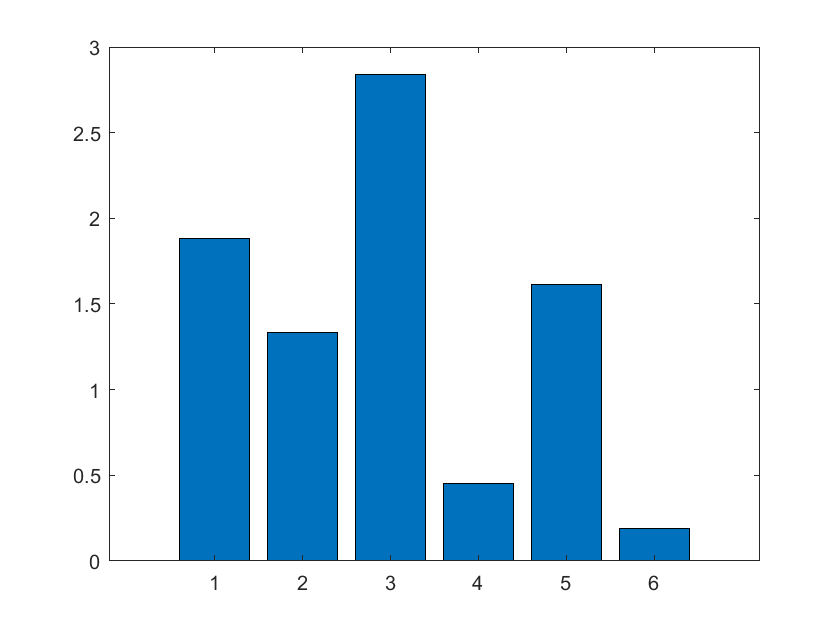

Unrecognized function or variable 'channels'.

Error in compareBetaBarChart (line 33)
set(gca,'xticklabel', {channels})

%    compareBetaBarChart(startindex, leng, js, channelsLeft); 

    disp("Beta bar chart summary for the RIGHT")
    compareBetaBarChart(startindex, leng, js, channelsRight);
    figure;

#### All frequency spectrum for max beta contacts

For the contact pair that is determined to produce the most beta, full spectrum analysis was performed. Delta is defined as between 0-4.99Hz, theta is between 5-8.99Hz, alpha is 9-11.99Hz, beta is 12-33.99Hz, and gamma is from 34-100Hz. Data is shown for the left and right. 

    disp("All frequency bar chart summary for the LEFT")
    allFreqBarChart(startindex, leng, js, highestBetas{1})
    figure;
    disp("All frequency bar chart summary for the Right")
    allFreqBarChart(startindex, leng, js, highestBetas{2}) 
    figure;

#### Mean and Standard Deviation for each Trial

In descending order of beta activity, the means and stds of each contact pair is displayed. Each contact pair has the mean and std for each trial listed. These values come only from the beta region. A more concise visualization is below. Data is for the left and right. 

   %% 
   disp("Table trial summary for the LEFT")
   maxMeanBetaAllRuns(startindex, js, leng, channelsLeft); 
   disp("Table trial summary for the RIGHT")
   maxMeanBetaAllRuns(startindex, js, leng, channelsRight);

#### Visualization of Trial Variability

For each contact, all three trials are plotted together to illustrate the variability from run-to-run for each Brainsense survey. Data has undergone smoothing that maintains the shape but not nessicarily the values. More granular information is in the table above. 

   disp("Graph trial summary for the LEFT")

Graph trial summary for the LEFT


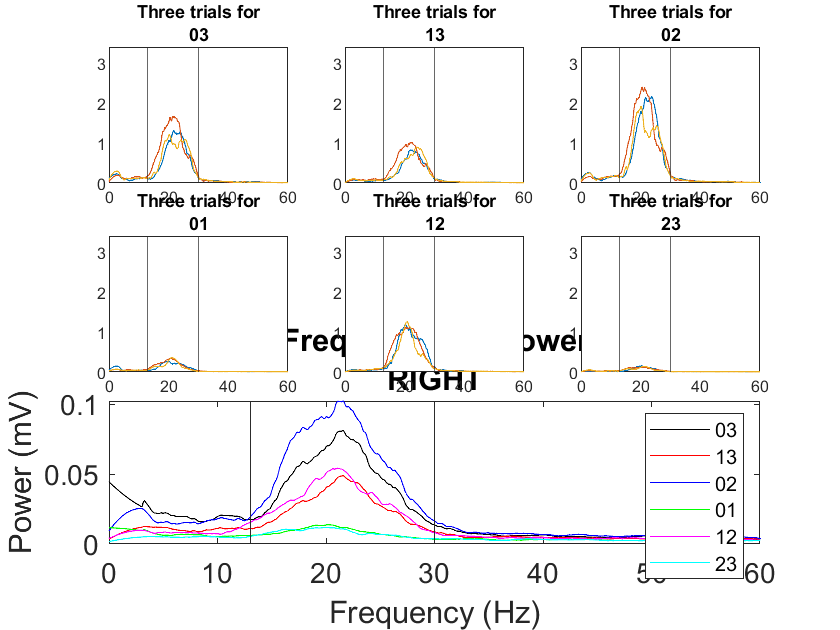

   %max is 2.8 
   %mleft = max(maxValuesLeft); 
   graphEachTrials(startindex, js, leng, channelsLeft, max(maxValuesLeft));

   figure;
   disp("Graph trial summary for the RIGHT")

Graph trial summary for the RIGHT


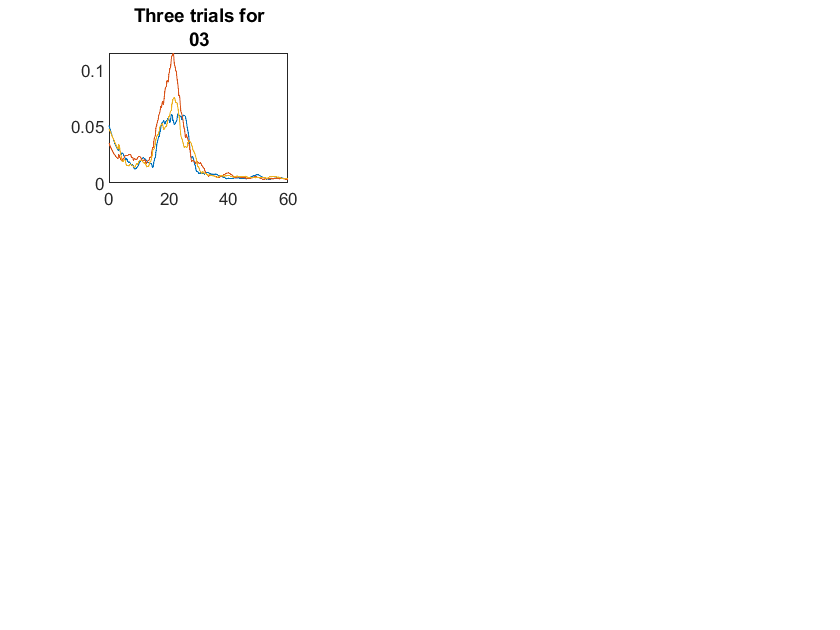

Not enough input arguments.

Error in graphEachTrials (line 33)
    ylim([0 maxval*1.2])

   graphEachTrials(startindex, js, leng, channelsRight);